**E3DSB Opgaver 4**

**Opgave 4.3**

clear all; clc; close all;

FIR-filterets impulsrespons er givet ved:

$h\left(n\right)=3\delta \left(n\right)-\delta \left(n-1\right)+2\delta \left(n-2\right)$. Da filterets impulsrespons er præcis filterkoefficienterne, har vi

h = [3 -1 2];
b = h;

på denne akse:

n = 0:2;

a) Skitsér impulsrespons

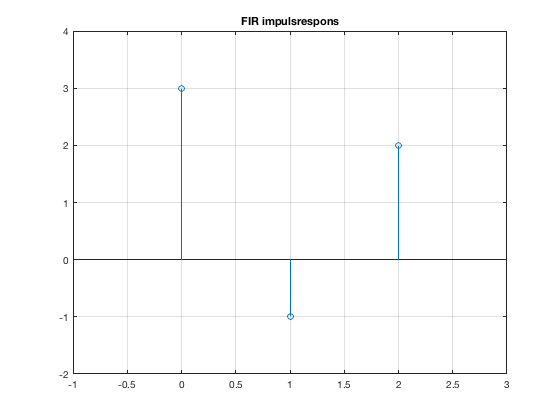

close all;

t = 'FIR impulsrespons';
stem(n,h); xlim([-1 3]); ylim([-2 4]); grid on; axis on;
title(t);

b) Differensligning (beregningsformel) for et FIR-filter skrives generelt ved foldningssummen:


$$y\left(n\right)=\sum_{k=0}^{M-1} h\left(k\right)x\left(n-k\right)$$


Hvilket specifikt for dette filter, med $M=3$ er:


$$y\left(n\right)=\sum_{k=0}^2 h\left(k\right)x\left(n-k\right)=h\left(0\right)x\left(n\right)+h\left(1\right)x\left(n-1\right)+h\left(2\right)x\left(n-2\right)=3x\left(n\right)-x\left(n-1\right)+2x\left(n-2\right)$$


c+d) Filterets respons $y\left(n\right)$ ved inputtet $x\left(n\right)=\left\lbrace 7,5,1\right\rbrace$, dvs. $N=3$.

x = [7 5 1];

Dette beregnes ved foldning... Eller med matlabs conv(). Længden på foldningssummen vil være $M+N-1=5$.

y = conv(x,h)

y =     21     8    12     9     2


e) Blokdiagram for filteret, baseret på differensligningen.